# Thermodynamically constrain Recon3D

## **Author: Ronan Fleming, **School of Medicine, University of Galway

## **Reviewers: **

## INTRODUCTION

In flux balance analysis of genome scale stoichiometric models of metabolism, the principal constraints are uptake or secretion rates, the steady state mass conservation assumption and reaction directionality. Von Bertylanffy [1,4] is a set of methods for (i) quantitative estimation of thermochemical parameters for metabolites and reactions using the component contribution method [3], (ii) quantitative assignment of reaction directionality in a multi-compartmental genome scale model based on an application of the second law of thermodynamics to each reaction [2], (iii) analysis of thermochemical parameters in a network context, and (iv) thermodynamically constrained flux balance analysis. The theoretical basis for each of these methods is detailed within the cited papers.

## PROCEDURE

## Configure the environment

The default COBRA Toolbox paths are automatically changed here to work on the new version of vonBertalanffy

aPath = which('initVonBertalanffy');
basePath = strrep(aPath,['vonBertalanffy' filesep 'initVonBertalanffy.m'],'');
addpath(genpath(basePath))
folderPattern=[filesep 'old'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,['vonBertalanffy' filesep 'initVonBertalanffy.m'],'');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'add';
editCobraToolboxPath(basePath,folderPattern,method)

adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/new


All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

initVonBertalanffy

ChemAxon Marvin Beans is installed and working.
	linux-vdso.so.1 (0x00007ffdddfcf000)
	libc.so.6 => /lib/x86_64-linux-gnu/libc.so.6 (0x00007ff1adeef000)
	libopenbabel.so.5 => /usr/lib/libopenbabel.so.5 (0x00007ff1adc9f000)
	libstdc++.so.6 => /usr/lib/x86_64-linux-gnu/libstdc++.so.6 (0x00007ff1ada85000)
	libgcc_s.so.1 => /usr/local/bin/MATLAB/R2021a/sys/os/glnxa64/libgcc_s.so.1 (0x00007ff1ad86d000)
	/lib64/ld-linux-x86-64.so.2 (0x00007ff1ae10f000)
	libdl.so.2 => /lib/x86_64-linux-gnu/libdl.so.2 (0x00007ff1ad865000)
	libz.so.1 => /lib/x86_64-linux-gnu/libz.so.1 (0x00007ff1ad849000)
	libm.so.6 => /lib/x86_64-linux-gnu/libm.so.6 (0x00007ff1ad6fa000)
	libgomp.so.1 => /usr/lib/x86_64-linux-gnu/libgomp.so.1 (0x00007ff1ad6b5000)
	libpthread.so.0 => /lib/x86_64-linux-gnu/libpthread.so.0 (0x00007ff1ad692000)

babel must depend on the system libstdc++.so.6 not the one from MATLAB
Trying to edit the 'LD_LIBRARY_PATH' to make sure that it has the correct system path before the Matlab path!
The solu

# Select the model

This tutorial is tested for the E. coli model iAF1260 and the human metabolic model Recon3Dmodel. However, only the data for the former is provided within the COBRA Toolbox as it is used for testing von Bertylanffy. However, the figures generated below are most suited to plotting results for Recon3D, so they may not be so useful for iAF1260.  The Recon3D example uses values from literature for input variables where they are available.

%modelName = 'iAF1260';
%modelName='Ec_iAF1260_flux1'; 
% uncomment this line and comment the line below if you want to use the other model-  currently will not work without changes
modelName='Recon3DModel_301'; 

## Load a model

Load a model, and save it as the original model in the workspace, unless it is already loaded into the workspace. 

clear model
global CBTDIR
modelFileName = [modelName '.mat']

modelFileName = 'Recon3DModel_301.mat'



modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded

switch modelName
    case 'Ec_iAF1260_flux1'
        modelFileName = [modelName '.xml']
        model = readCbModel(modelFileName);
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[Cytosol]', model.mets))=0; % One reaction needing charge balancing
        
    case 'iAF1260'
        model = readCbModel(modelFileName);
        model.mets = cellfun(@(mets) strrep(mets,'_c','[c]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_e','[e]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_p','[p]'),model.mets,'UniformOutput',false);
        bool = strcmp(model.mets,'lipa[c]old[c]');
        model.mets{bool}='lipa_old_[c]';
        bool = strcmp(model.mets,'lipa[c]old[e]');
        model.mets{bool}='lipa_old_[e]';
        bool = strcmp(model.mets,'lipa[c]old[p]');
        model.mets{bool}='lipa_old_[p]';
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[c]', model.mets))=0; % One reaction needing charge balancing
        
    case 'Recon3DModel_Dec2017'
      model = readCbModel(modelFileName);
      model.csense(1:size(model.S,1),1)='E';
      %Hack for thermodynamics
      model.metFormulas{strcmp(model.mets,'h[i]')}='H';
      model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
      if isfield(model,'metCharge')
          model.metCharges = double(model.metCharge);
          model=rmfield(model,'metCharge');
      end
      modelOrig = model;
   case 'Recon3DModel_301'
      model = readCbModel(modelFileName);
          %Hack for thermodynamics
      model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
      modelOrig = model;
    otherwise
            error('setup specific parameters for your model')
end

Each model.subSystems{x} has been changed to a character array.


## Set the directory containing the results

switch modelName
    case 'Ec_iAF1260_flux1'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'iAF1260'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'Recon3DModel_Dec2017'
        basePath='~/work/sbgCloud';
        resultsPath=[basePath '/programReconstruction/projects/recon2models/results/thermo/' modelName];
        resultsBaseFileName=[resultsPath filesep modelName '_' datestr(now,30) '_'];
    case 'Recon3DModel_301'
        basePath=['~' filesep 'work' filesep 'sbgCloud'];
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,[filesep 'tutorial_vonBertalanffy.mlx'],'');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results_'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the directory containing molfiles

switch modelName
    case 'Ec_iAF1260_flux1'
        molFileDir = 'iAF1260Molfiles';
    case 'iAF1260'
        molFileDir = 'iAF1260Molfiles';
    case 'Recon3DModel_Dec2017'
        molFileDir = [basePath '/data/metDatabase/explicit/molFiles'];
        %molFileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBimplicitHMol'];
        %molFileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBexplicitHMol'];
    case 'Recon3DModel_301'
        ctfPath = [basePath filesep 'code' filesep 'fork-ctf'];
        % system(['git clone https://github.com/opencobra/ctf' ctfPath])
        molFileDir = [basePath filesep 'code' filesep 'fork-ctf' filesep 'mets' filesep 'molFiles'];
    otherwise
        molFileDir = [basePath '/code/fork-ctf/mets/molFiles'];
end

## Set the thermochemical parameters for the model

switch modelName
    case 'Ec_iAF1260_flux1'
        T = 310.15; % Temperature in Kelvin
        compartments = {'Cytosol'; 'Extra_organism'; 'Periplasm'}; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV        
    case 'iAF1260'
        T = 310.15; % Temperature in Kelvin
        compartments = ['c'; 'e'; 'p']; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV
    case 'Recon3DModel_Dec2017'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    case 'Recon3DModel_301'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    otherwise
        error('setup specific parameters for your model')
end

## Set the default range of metabolite concentrations

switch modelName
    case 'Ec_iAF1260_flux1'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'iAF1260'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'Recon3DModel_Dec2017'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    case 'Recon3DModel_301'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    otherwise
        error('setup specific parameters for your model')
end

## Set the desired confidence level for estimation of thermochemical parameters

The confidence level for estimated standard transformed reaction Gibbs energies is used to quantitatively assign reaction directionality.

switch modelName
    case 'Ec_iAF1260_flux1'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol    
    case 'iAF1260'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    case 'Recon3DModel_Dec2017'
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    otherwise
        confidenceLevel = -1;%bypass addition of uncertainty temporarily
        %confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
end

## Prepare folder for results

if ~exist(resultsPath,'dir')
    mkdir(resultsPath)
end
cd(resultsPath)

## Set the print level and decide to record a diary or not (helpful for debugging)

printLevel=2;

diary([resultsPath filesep 'diary.txt'])

# Setup a thermodynamically constrained model

## Read in the metabolite bounds

setDefaultConc=1;
setDefaultFlux=0;
rxnBoundsFile=[];
model=readMetRxnBoundsFiles(model,setDefaultConc,setDefaultFlux,concMinDefault,concMaxDefault,metBoundsFile,rxnBoundsFile,printLevel);

Reading metabolite conc bounds from: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/experimentalData/metaboliteConcentrations/HumanCofactorConcentrations.txt
              adp[c]	     1e-07	    0.0019
              adp[m]	    0.0026	    0.0094
              amp[c]	     1e-07	    0.0012
              atp[c]	   0.00129	    0.0049
              atp[m]	    0.0028	    0.0204
              coa[c]	  2.92e-05	 0.0001168
              coa[m]	    0.0022	    0.0039
              na1[c]	     1e-07	     0.025
              na1[e]	    0.1326	    0.1554
              nad[c]	0.00010546	 0.0007572
              nad[m]	    0.0005	    0.0075
             nadh[c]	9.2574e-07	0.00038294
             nadh[m]	     1e-07	    0.0011
             nadp[c]	     1e-07	5.8284e-06
             nadp[m]	     1e-07	    0.0015
            nadph[c]	     1e-07	0.00037523
            nadph[m]	     1e-07	    0.0042
              nh4[c]	    0.0007	    0.0009
               pi[c]	     0.001	    0.0063


## Check inputs

model = configureSetupThermoModelInputs(model,T,compartments,ph,is,chi,concMinDefault,concMaxDefault,confidenceLevel);


Field metCompartments is missing from model structure. Attempting to create it.
Attempt to create field metCompartments successful.



## Add InChI to model

%[model, pKaErrorMets] = setupComponentContribution(model,molFileDir);
model = addInchiToModel(model, molFileDir, 'sdf', printLevel);

Creating MetStructures.sdf from molfiles.
Percentage of metabolites without mol files: 9.1%
Converting SDF to InChI strings.
5835 = number of model metabolites
5835 ... with mol files
0 ... without mol files
4949 ... with nonstandard inchi
886 ... without nonstandard inchi
108 ... compositie inchi removed


## Add pseudoisomers to model

[model, nonphysicalMetBool, pKaErrorMetBool] = addPseudoisomersToModel(model, printLevel);

Estimating metabolite pKa values.

ChemAxon's pKa calculator plugin returned an error for 2 metabolites:
    {'CE6252'      }    {'InChI=1/C5H3N4O3/c10-3-1-2(7-4(11)6-1)8-5(12)9-3/h(H3,6,7…'}
    {'pchol2ste_hs'}    {'InChI=1/C26H55NO7P/c1-5-6-7-8-9-10-11-12-13-14-15-16-17-1…'}

Assuming that metabolite species in model.metFormulas are representative for metabolites where pKa could not be estimated.
5835 = number of model metabolites
217 = number of nonphysical model metabolites
3 = number of model metabolites with pKa error


#### Check elemental balancing of metabolic reactions

ignoreBalancingOfSpecifiedInternalReactions=1;
if ~exist('massImbalance','var')
    if isfield(model,'Srecon')
        model.S=model.Srecon;
    end
    % Check for imbalanced reactions
    fprintf('\nChecking mass and charge balance.\n');
    %Heuristically identify exchange reactions and metabolites exclusively involved in exchange reactions
    if ~isfield(model,'SIntMetBool')  ||  ~isfield(model,'SIntRxnBool') || ignoreBalancingOfSpecifiedInternalReactions
        %finds the reactions in the model which export/import from the model
        %boundary i.e. mass unbalanced reactions
        %e.g. Exchange reactions
        %     Demand reactions
        %     Sink reactions
        model = findSExRxnInd(model,[],printLevel);
    end
    
    if ignoreBalancingOfSpecifiedInternalReactions
        [nMet,nRxn]=size(model.S);
        ignoreBalancingMetBool=false(nMet,1);
        for m=1:nMet
%             if strcmp(model.mets{m},'Rtotal3coa[m]')
%                 pause(0.1);
%             end
            if ~isempty(model.metFormulas{m})
                ignoreBalancingMetBool(m,1)=numAtomsOfElementInFormula(model.metFormulas{m},'FULLR');
            end
        end
        ignoreBalancingRxnBool=getCorrespondingCols(model.S,ignoreBalancingMetBool,model.SIntRxnBool,'inclusive');
        SIntRxnBool=model.SIntRxnBool;
        model.SIntRxnBool=model.SIntRxnBool & ~ignoreBalancingRxnBool;
    end
    
    printLevelcheckMassChargeBalance=-1;  % -1; % print problem reactions to a file
    %mass and charge balance can be checked by looking at formulas
    [massImbalance,imBalancedMass,imBalancedCharge,imBalancedRxnBool,Elements,missingFormulaeBool,balancedMetBool]...
        = checkMassChargeBalance(model,printLevelcheckMassChargeBalance,resultsBaseFileName);
    model.balancedRxnBool=~imBalancedRxnBool;
    model.balancedMetBool=balancedMetBool;
    model.Elements=Elements;
    model.missingFormulaeBool=missingFormulaeBool;
    
    %reset original boolean vector
    if ignoreBalancingOfSpecifiedInternalReactions
        model.SIntRxnBool=SIntRxnBool;
    end
end


Checking mass and charge balance.


Assuming biomass reaction is: biomass_maintenance
ATP demand reaction is not considered an exchange reaction by default. It should be mass balanced:
DM_atp_c_	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 


There are mass imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/Recon3DModel_301_results_mass_imbalanced_reactions.txt
There are mass balanced, but charge imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/Recon3DModel_301_results_charge_imbalanced_reactions.txt


## Create the thermodynamic training model

if 0
    %use previously generated training model
    aPath = which('driver_createTrainingModel.mlx');
    aPath = strrep(aPath,['new' filesep 'driver_createTrainingModel.mlx'],['cache' filesep]);
    load([aPath 'trainingModel.mat'])
else
    %recreate the trainingModel
    driver_createTrainingModel
end

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
ad

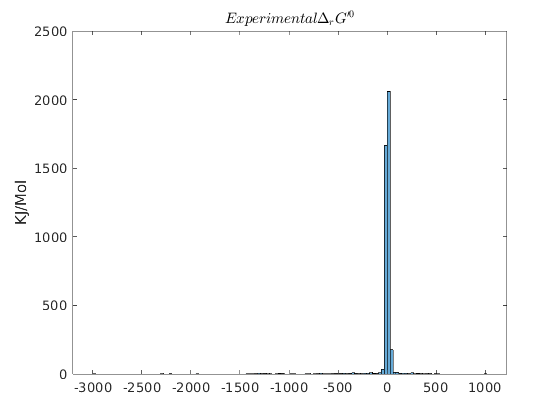

figure
histogram(trainingModel.DrGt0)
title('$Experimental \smallskip \Delta_{r} G^{\prime0}$','Interpreter','latex')
ylabel('KJ/Mol')

fprintf('%u%s\n',nnz(trainingModel.DrGt0==0),' = number of zero DrGt0, i.e. experimental apparent equilibrium constant equal to one') 

35 = number of zero DrGt0, i.e. experimental apparent equilibrium constant equal to one


formulas = printRxnFormula(trainingModel,trainingModel.rxns(trainingModel.DrGt0==0));

TECRDB_79	C01101 	<=>	C00231 
TECRDB_244	C00041 	<=>	C00133 
TECRDB_580	C00002 + C00065 + C01650 	<=>	C00013 + C00020 + C02553 
TECRDB_698	C00003 + C00644 	<=>	C00004 + C00085 
TECRDB_733	C01101 	<=>	C00231 
TECRDB_815	C00002 + C00055 	<=>	C00008 + C00112 
TECRDB_1090	C00001 + C00006 + C00311 	<=>	C00005 + C00026 + C00288 
TECRDB_1272	C00001 + C06322 	<=>	C06749 
TECRDB_2030	C00041 	<=>	C00133 
TECRDB_2202	C00003 + C00579 	<=>	C00004 + C00248 
TECRDB_2339	C00063 + C00103 	<=>	C00013 + C00501 
TECRDB_2392	C01213 	<=>	C00683 
TECRDB_2584	C00041 	<=>	C00133 
TECRDB_2620	C00026 + C00041 	<=>	C00022 + C00025 
TECRDB_2621	C00002 + C01107 	<=>	C00008 + C01143 
TECRDB_2629	C00025 	<=>	C00217 
TECRDB_2639	C00002 + C00104 	<=>	C00008 + C00081 
TECRDB_2746	C00031 	<=>	C00095 
TECRDB_2791	C00010 + C00042 + C00044 	<=>	C00009 + C00035 + C00091 
TECRDB_2841	2 C00008 	<=>	C00002 + C00020 
TECRDB_2894	C00041 	<=>	C00133 
TECRDB_3608	C00031 	<=>	C00095 
TECRDB_3640	C00047 	<=>	C00739 
TECRDB_3803	C0063

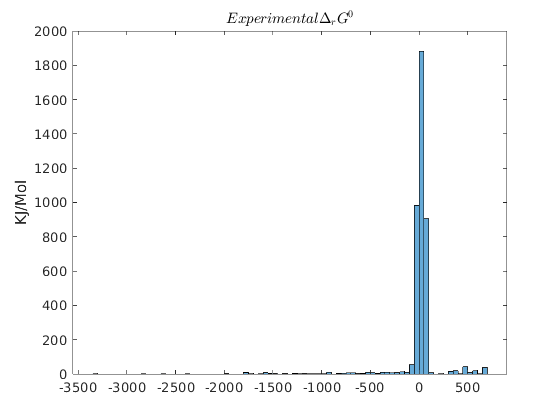

figure
histogram(trainingModel.DrG0)
title('$Experimental \medskip \Delta_{r} G^{0}$','Interpreter','latex')
ylabel('KJ/Mol')

fprintf('%u%s\n',nnz(trainingModel.DrG0==0),' = number of zero DrG0. i.e. equilibrium constant equal to one and same number of hydrogens on both sides') 

16 = number of zero DrG0. i.e. equilibrium constant equal to one and same number of hydrogens on both sides


formulas = printRxnFormula(trainingModel,trainingModel.rxns(trainingModel.DrG0==0));

TECRDB_79	C01101 	<=>	C00231 
TECRDB_244	C00041 	<=>	C00133 
TECRDB_733	C01101 	<=>	C00231 
TECRDB_1272	C00001 + C06322 	<=>	C06749 
TECRDB_2030	C00041 	<=>	C00133 
TECRDB_2392	C01213 	<=>	C00683 
TECRDB_2584	C00041 	<=>	C00133 
TECRDB_2629	C00025 	<=>	C00217 
TECRDB_2894	C00041 	<=>	C00133 
TECRDB_3640	C00047 	<=>	C00739 
TECRDB_4052	C00041 	<=>	C00133 
TECRDB_4271	C00935 	<=>	C00190 
TECRDB_4375	C00123 	<=>	C01570 
FORM_C00023		<=>	C00023 
FORM_C00034		<=>	C00034 
FORM_C00080		<=>	C00080 


## Create Group Incidence Matrix

Create the group incidence matrix (G) for the combined set of all metabolites.

save('data_prior_to_createGroupIncidenceMatrix')

%param.fragmentationMethod='manual';
param.fragmentationMethod='abinito';
param.printLevel=0;
param.modelCache=['autoFragment_' modelName];
param.debug=1;
param.radius=2;

combinedModel = createGroupIncidenceMatrix(model, trainingModel, param);

Creating group incidence matrix
There are 574 fragments unique to the training model.
There are 914 fragments in common between the training and test models.
There are 2659 fragments unique to the test model.


save('data_prior_to_componentContribution','model','combinedModel')

## Apply component contribution method

if ~isfield(model,'DfG0')
    [model,solution] = componentContribution(model,combinedModel);
end

Running Component Contribution method


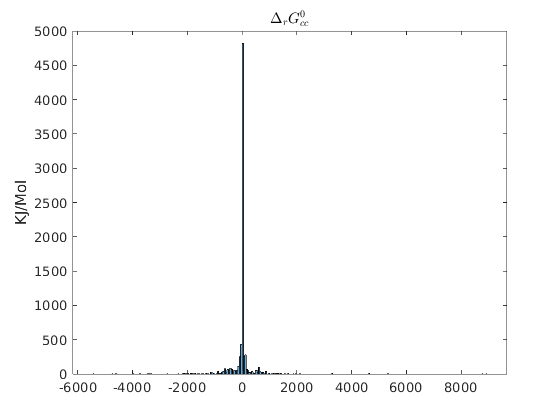

figure
histogram(model.DrG0(~model.unconstrainedDrG0_cc))
title('$\Delta_{r} G^{0}_{cc}$','Interpreter','latex')
ylabel('KJ/Mol')

fprintf('%u%s\n',length(model.DrG0),' model reactions') 

10600 model reactions


fprintf('%u%s\n',nnz(model.unconstrainedDrG0_cc),' of which have partially unconstrained groups in DrG0_cc') 

3147 of which have partially unconstrained groups in DrG0_cc


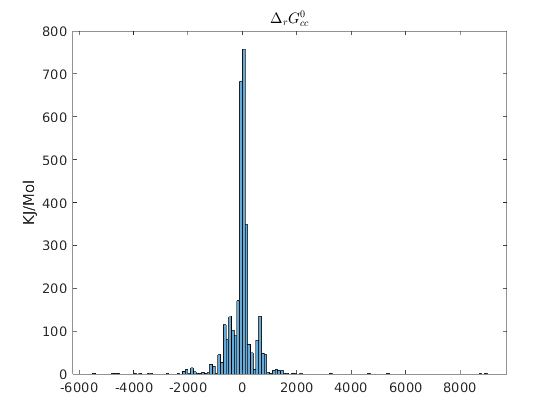

figure
model.transportRxnBool = transportReactionBool(model);
bool = model.SIntRxnBool & ~model.transportRxnBool & ~model.unconstrainedDrG0_cc;
histogram(model.DrG0(bool))
title('$\Delta_{r} G^{0}_{cc}$','Interpreter','latex')
ylabel('KJ/Mol')

fprintf('%u%s\n',length(model.DrG0),' model reactions') 

10600 model reactions


fprintf('%u%s\n',nnz(model.unconstrainedDrG0_cc),' of which have partially unconstrained groups in DrG0_cc') 

3147 of which have partially unconstrained groups in DrG0_cc


ind=find(model.unconstrainedDrG0_cc);
formulas = printRxnFormula(model,model.rxns(ind(1:10)));

2AMACSULT	2amac[c] + nadph[c] + paps[c] 	->	nadp[c] + Lcyst[c] + pap[c] 
2DR1PP	h2o[c] + 2dr1p[c] 	->	pi[c] + drib[c] 
34DHPLACOX	h2o[c] + nad[c] + 34dhpac[c] 	->	2 h[c] + nadh[c] + 34dhpha[c] 
34DHPLACOX_NADP_	h2o[c] + nadp[c] + 34dhpac[c] 	<=>	2 h[c] + nadph[c] + 34dhpha[c] 
34DHXMANDACOX	h2o[c] + nad[c] + 34dhmald[c] 	->	2 h[c] + nadh[c] + 34dhoxmand[c] 
34DHXMANDACOX_NADP_	h2o[c] + nadp[c] + 34dhmald[c] 	<=>	2 h[c] + nadph[c] + 34dhoxmand[c] 
3AIBTm	2mop[m] + glu_L[m] 	<=>	akg[m] + 3aib[m] 
3HAO	o2[c] + 3hanthrn[c] 	->	h[c] + cmusa[c] 
3HBCDm	h2o[m] + b2coa[m] 	<=>	3hbcoa_R[m] 
3HLYTCL	h[c] + 34dhphe[c] 	->	co2[c] + dopa[c] 


## Setup a thermodynamically constrained model

save('debug_prior_to_setupThermoModel')

if ~isfield(model,'DfGt0')
    model = setupThermoModel(model,confidenceLevel);
end


Estimating standard transformed Gibbs energies of formation.

Estimating bounds on transformed Gibbs energies.
Additional effect due to possible change in chemical potential of Hydrogen ions for transport reactions.
Additional effect due to possible change in electrical potential for transport reactions.


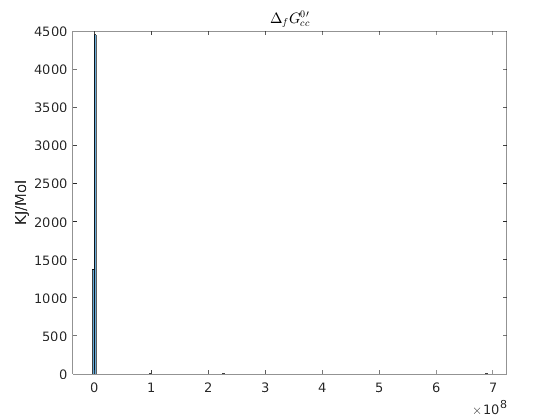

figure
histogram(model.DfGt0)
title('$\Delta_{f} G^{0\prime}_{cc}$','Interpreter','latex')
ylabel('KJ/Mol')

## Generate a model with reactants instead of major microspecies

if ~isfield(model,'Srecon') 
    printLevel_pHbalanceProtons=-1;
    model=pHbalanceProtons(model,massImbalance,printLevel_pHbalanceProtons,resultsBaseFileName);
end

## Determine quantitative directionality assignments

if ~exist('directions','var') |  1
    fprintf('Quantitatively assigning reaction directionality.\n');
    [model, directions] = thermoConstrainFluxBounds(model,confidenceLevel,DrGt0_Uncertainty_Cutoff,printLevel);
end

Quantitatively assigning reaction directionality.


9/10600 reactions with DrGtMin=DrGtMax~=0
4/10600 reactions with DrGtMin=DrGtMax=0
The following reactions have DrGtMax=DrGtMin=0:
H2Oter	h2o[c] 	<=>	h2o[r] 
H2Otn	h2o[n] 	<=>	h2o[c] 
Htr	h[c] 	<=>	h[r] 
HMR_1095	h[c] 	<=>	h[n] 
ACYP


## Analyse thermodynamically constrained model

Choose the cutoff for probablity that reaction is reversible

cumNormProbCutoff=0.2;

Build Boolean vectors with reaction directionality statistics

[model,directions]=directionalityStats(model,directions,cumNormProbCutoff,printLevel);

9/10600 reactions with DrGtMin=DrGtMax~=0
4/10600 reactions with DrGtMin=DrGtMax=0
Qualitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
      5208	 forward reconstruction assignment.
         4	 reverse reconstruction assignment.
      3579	 reversible reconstruction assignment.

Quantitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
      8036	 of which have a thermodynamic assignment.
       751	 of which have no thermodynamic assignment.
      1636	 forward thermodynamic only assignment.
      1512	 reverse thermodynamic only assignment.
      4888	 reversible thermodynamic only assignment.

Qualitiative vs Quantitative:
      2525	 Reversible -> Reversible
       347	 Reversible -> Forward
       583	 Reversible -> Reverse
       120	 Reversible -> Uncertain
      1286	 Forward -> Forward
       929	 Forward -> Reverse
      2362	 Forward -> Reversible
       631	 Forward -> Uncertain

% directions    a structue of boolean vectors with different directionality
%               assignments where some vectors contain subsets of others
%
% qualtiative -> quantiative changed reaction directions
%   .forward2Forward
%   .forward2Reverse
%   .forward2Reversible
%   .forward2Uncertain
%   .reversible2Forward
%   .reversible2Reverse
%   .reversible2Reversible
%   .reversible2Uncertain
%   .reverse2Forward
%   .reverse2Reverse
%   .reverse2Reversible
%   .reverse2Uncertain
%   .tightened
%
% subsets of qualtiatively forward  -> quantiatively reversible 
%   .forward2Reversible_bydGt0
%   .forward2Reversible_bydGt0LHS
%   .forward2Reversible_bydGt0Mid
%   .forward2Reversible_bydGt0RHS
% 
%   .forward2Reversible_byConc_zero_fixed_DrG0
%   .forward2Reversible_byConc_negative_fixed_DrG0
%   .forward2Reversible_byConc_positive_fixed_DrG0
%   .forward2Reversible_byConc_negative_uncertain_DrG0
%   .forward2Reversible_byConc_positive_uncertain_DrG0

Write out reports on directionality changes for individual reactions to the results folder.

fprintf('%s\n','directionalityChangeReport...');

directionalityChangeReport...


directionalityChangeReport(model,directions,cumNormProbCutoff,printLevel,resultsBaseFileName)

Generate pie charts with proportions of reaction directionalities and changes in directionality

fprintf('%s\n','directionalityStatFigures...');

directionalityStatFigures...


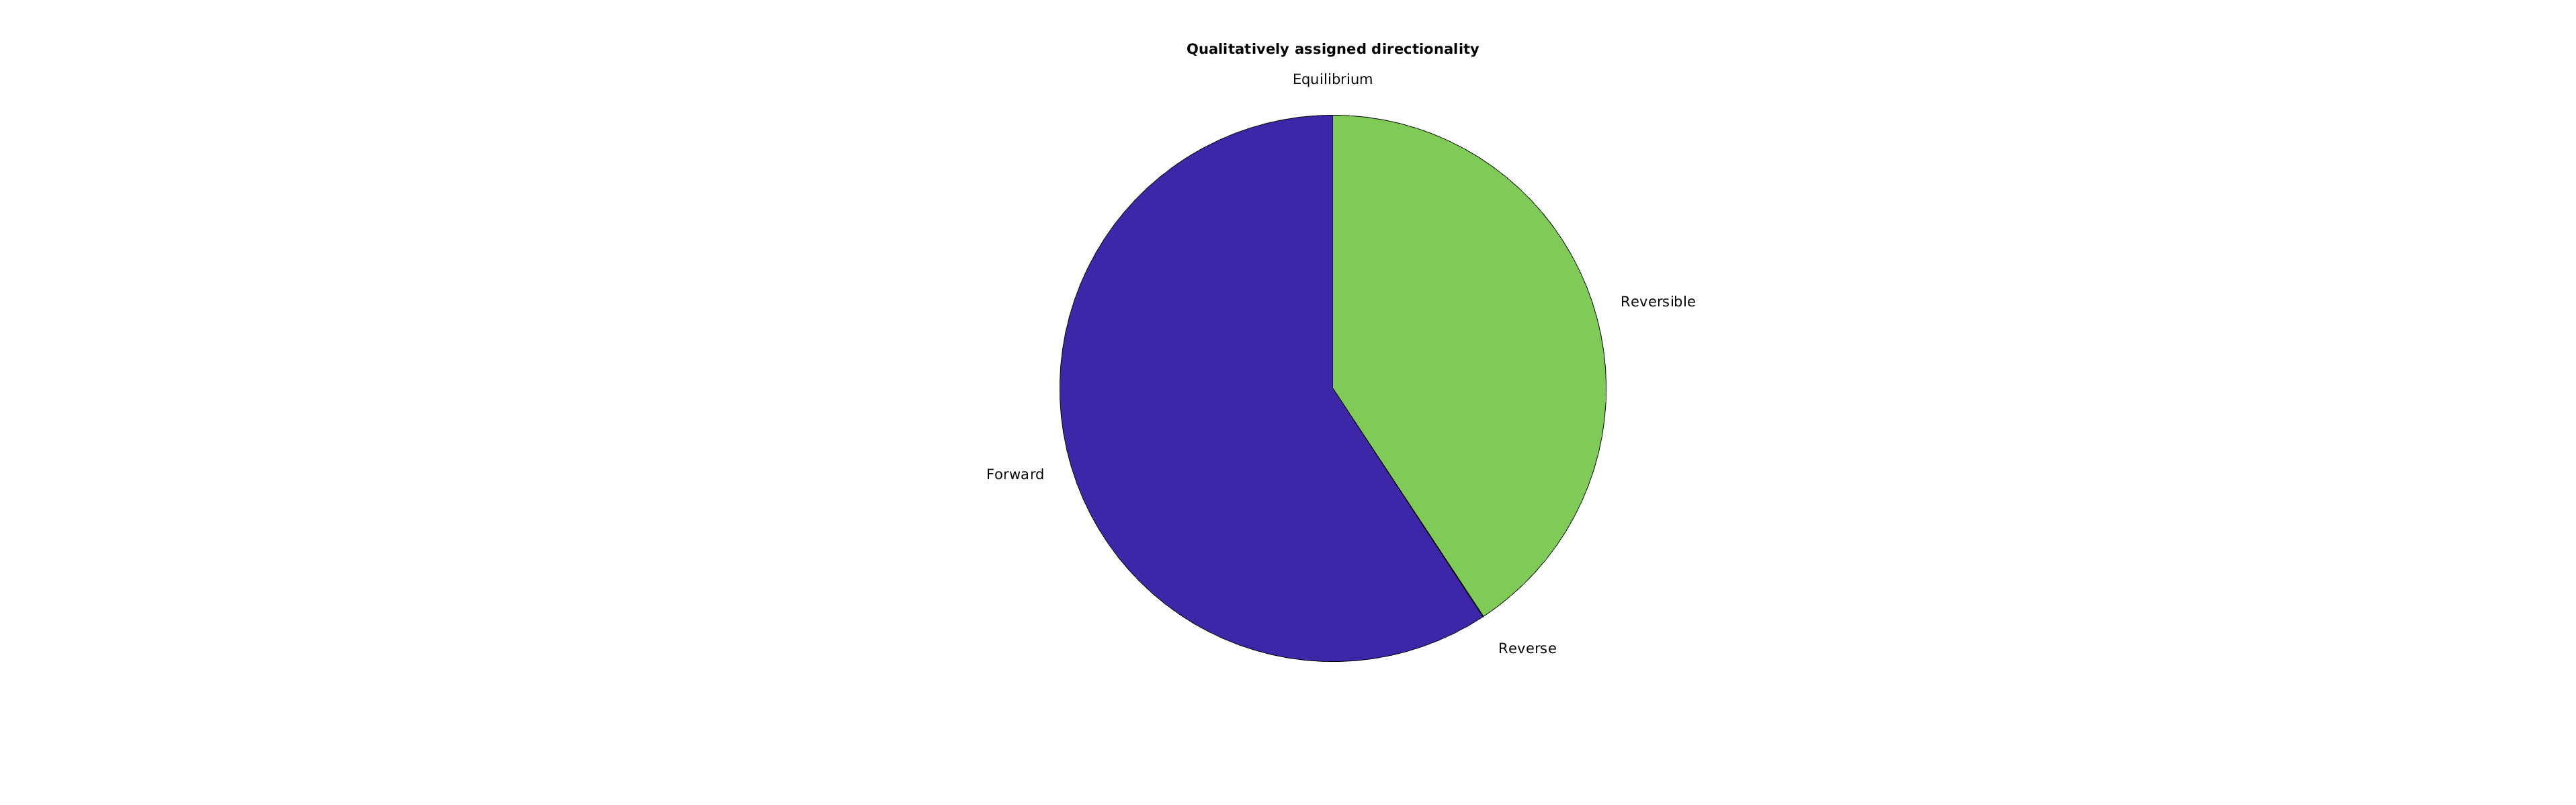

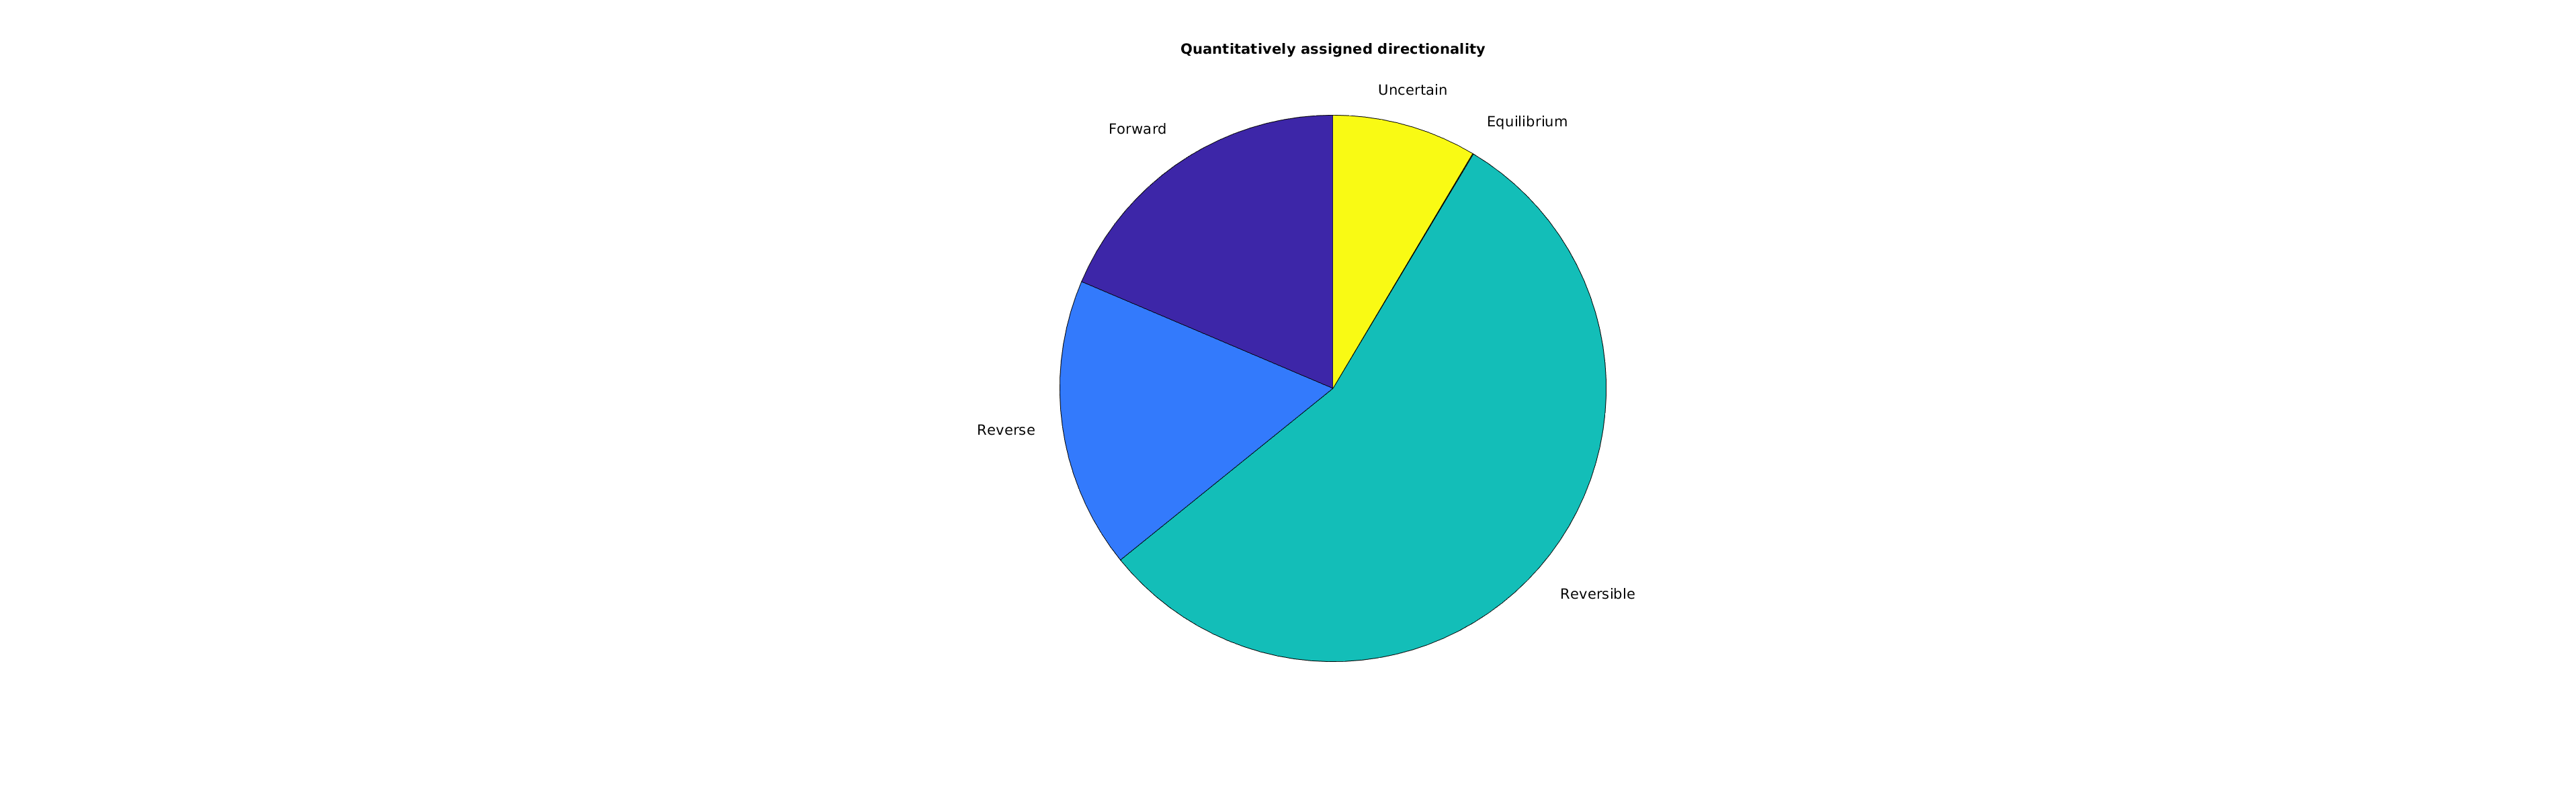

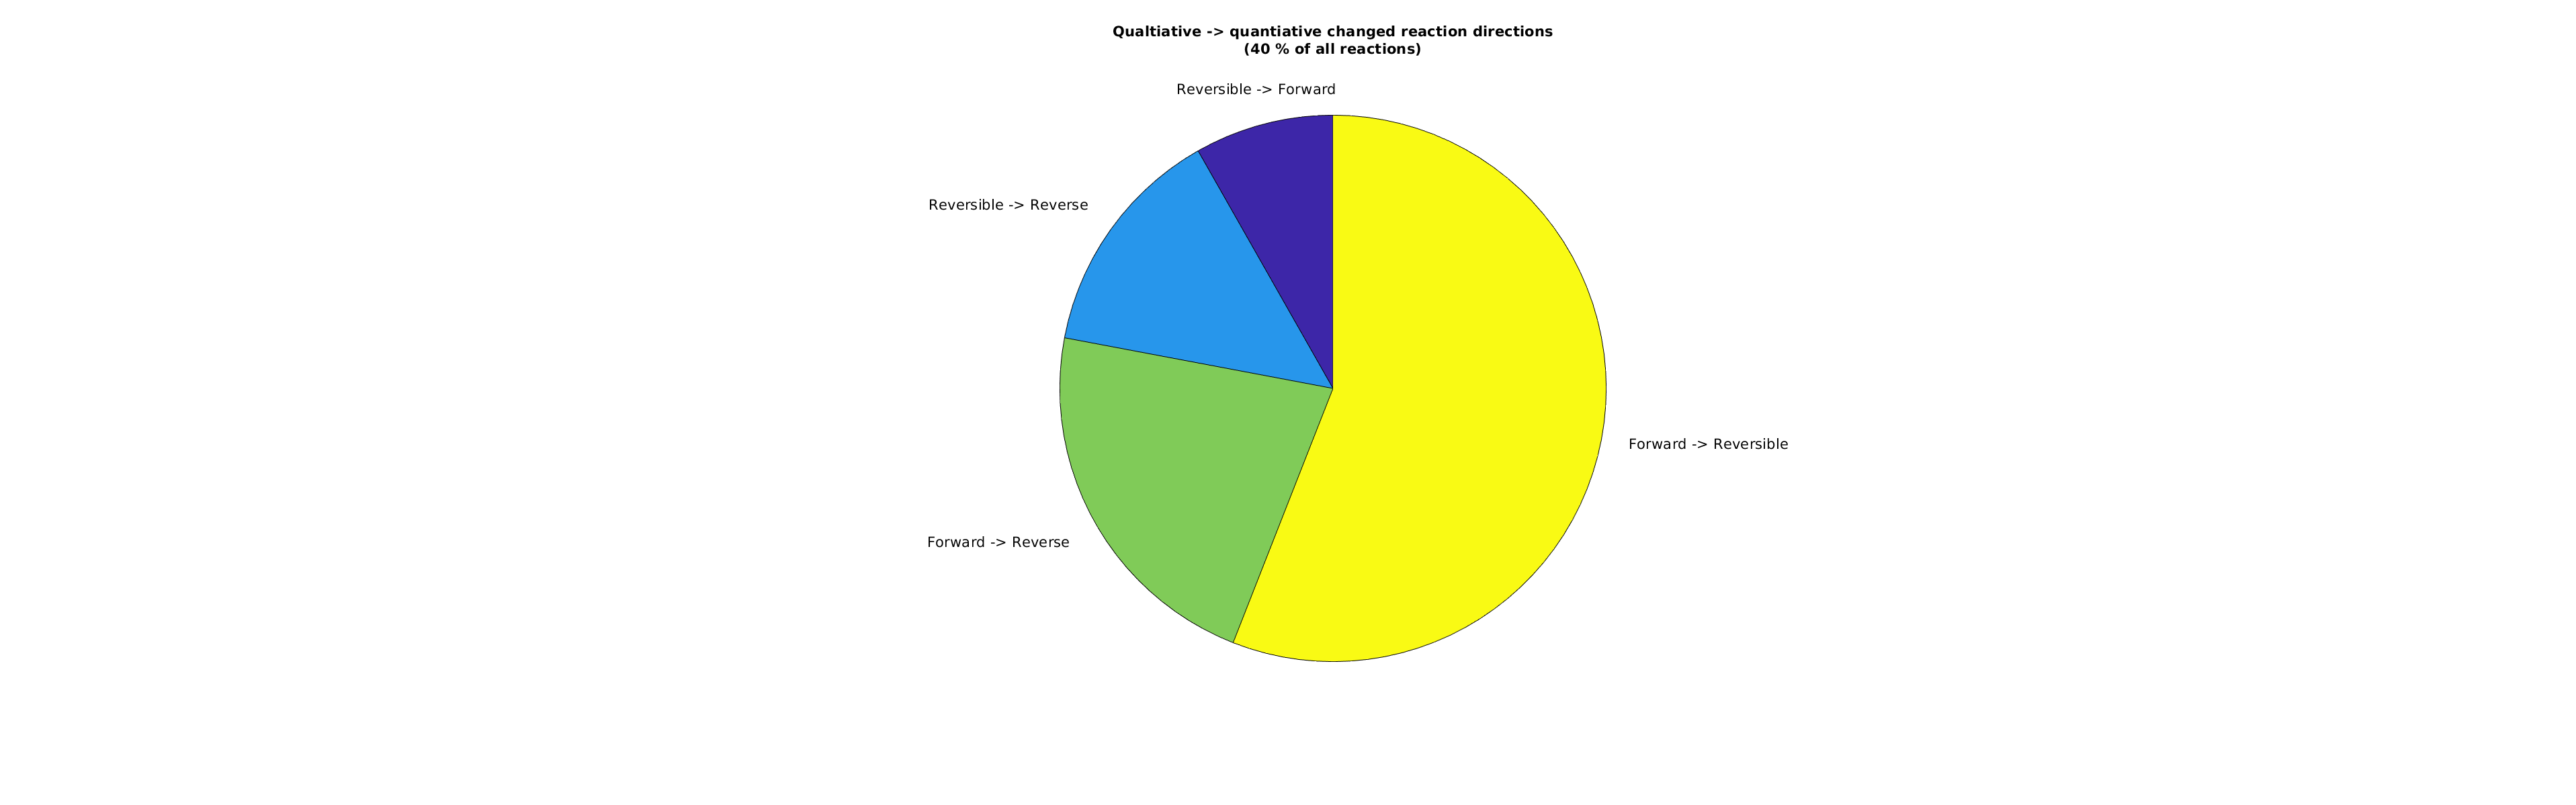

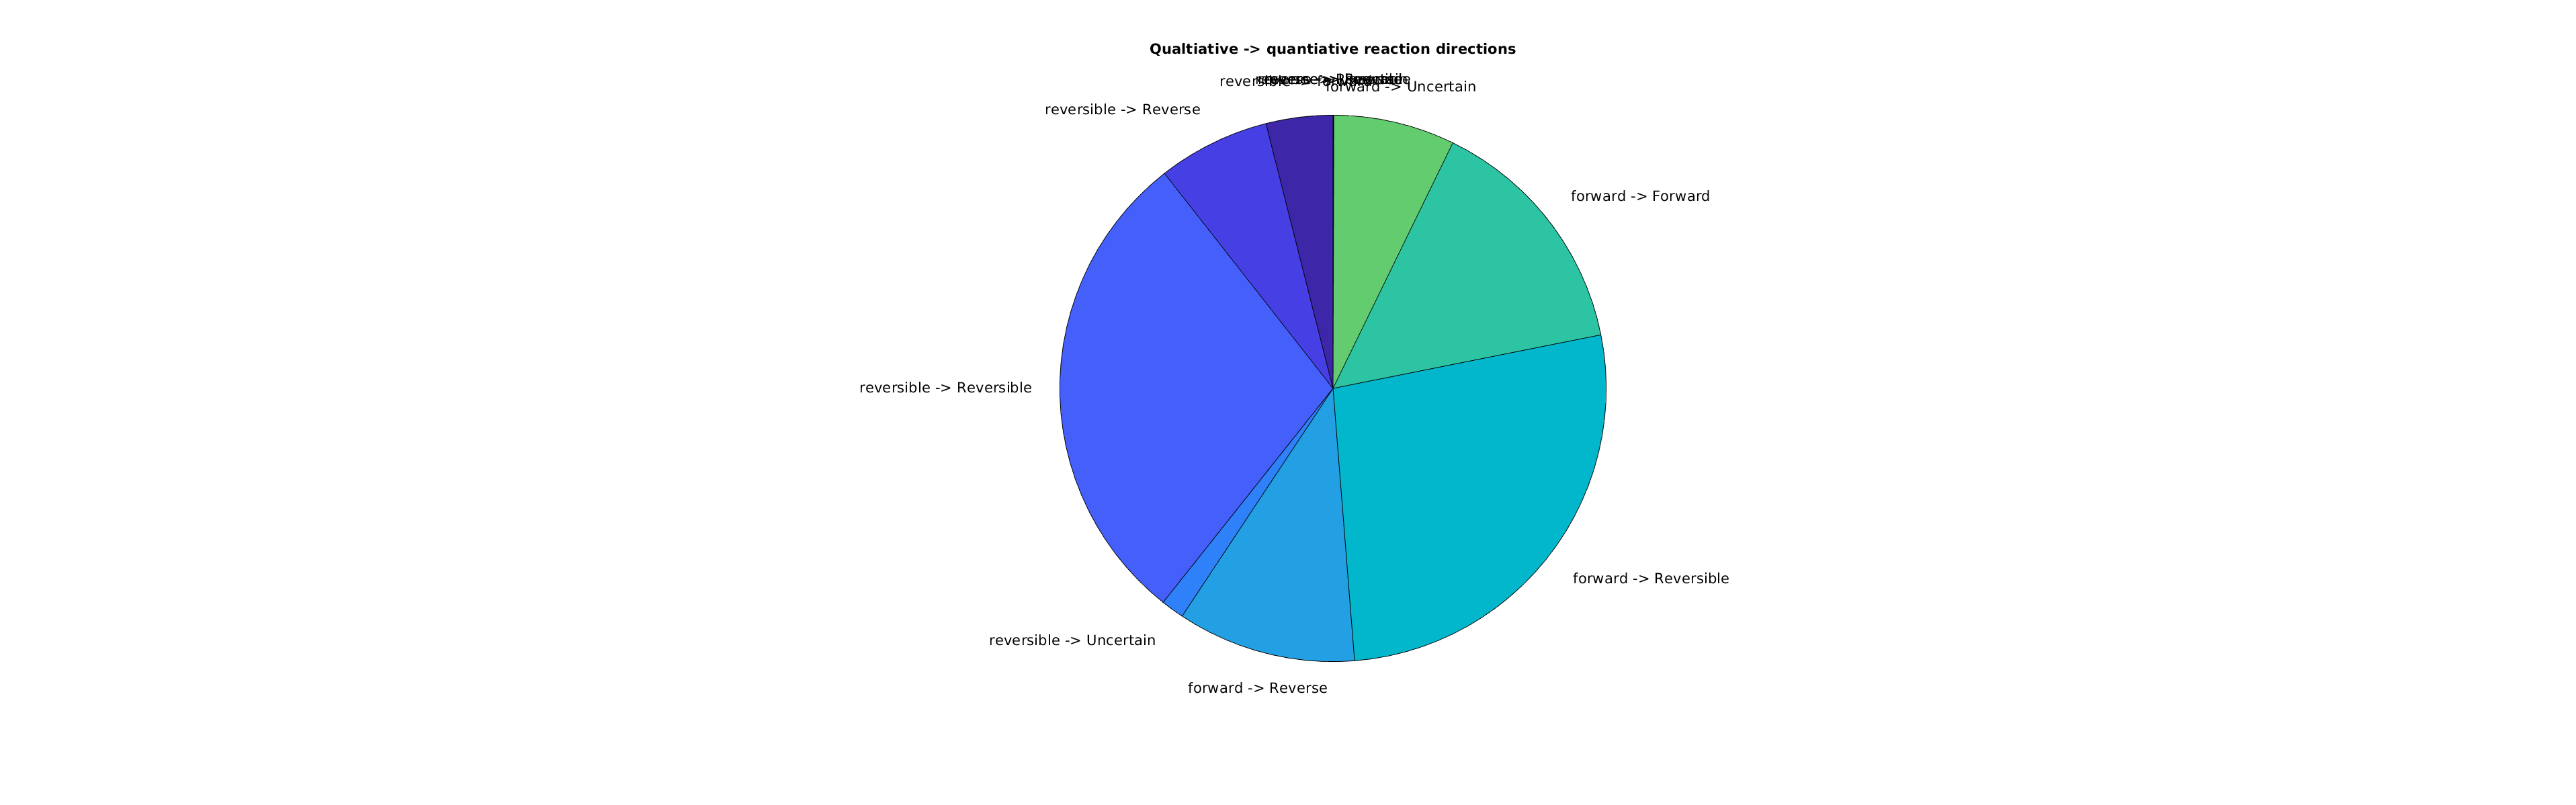

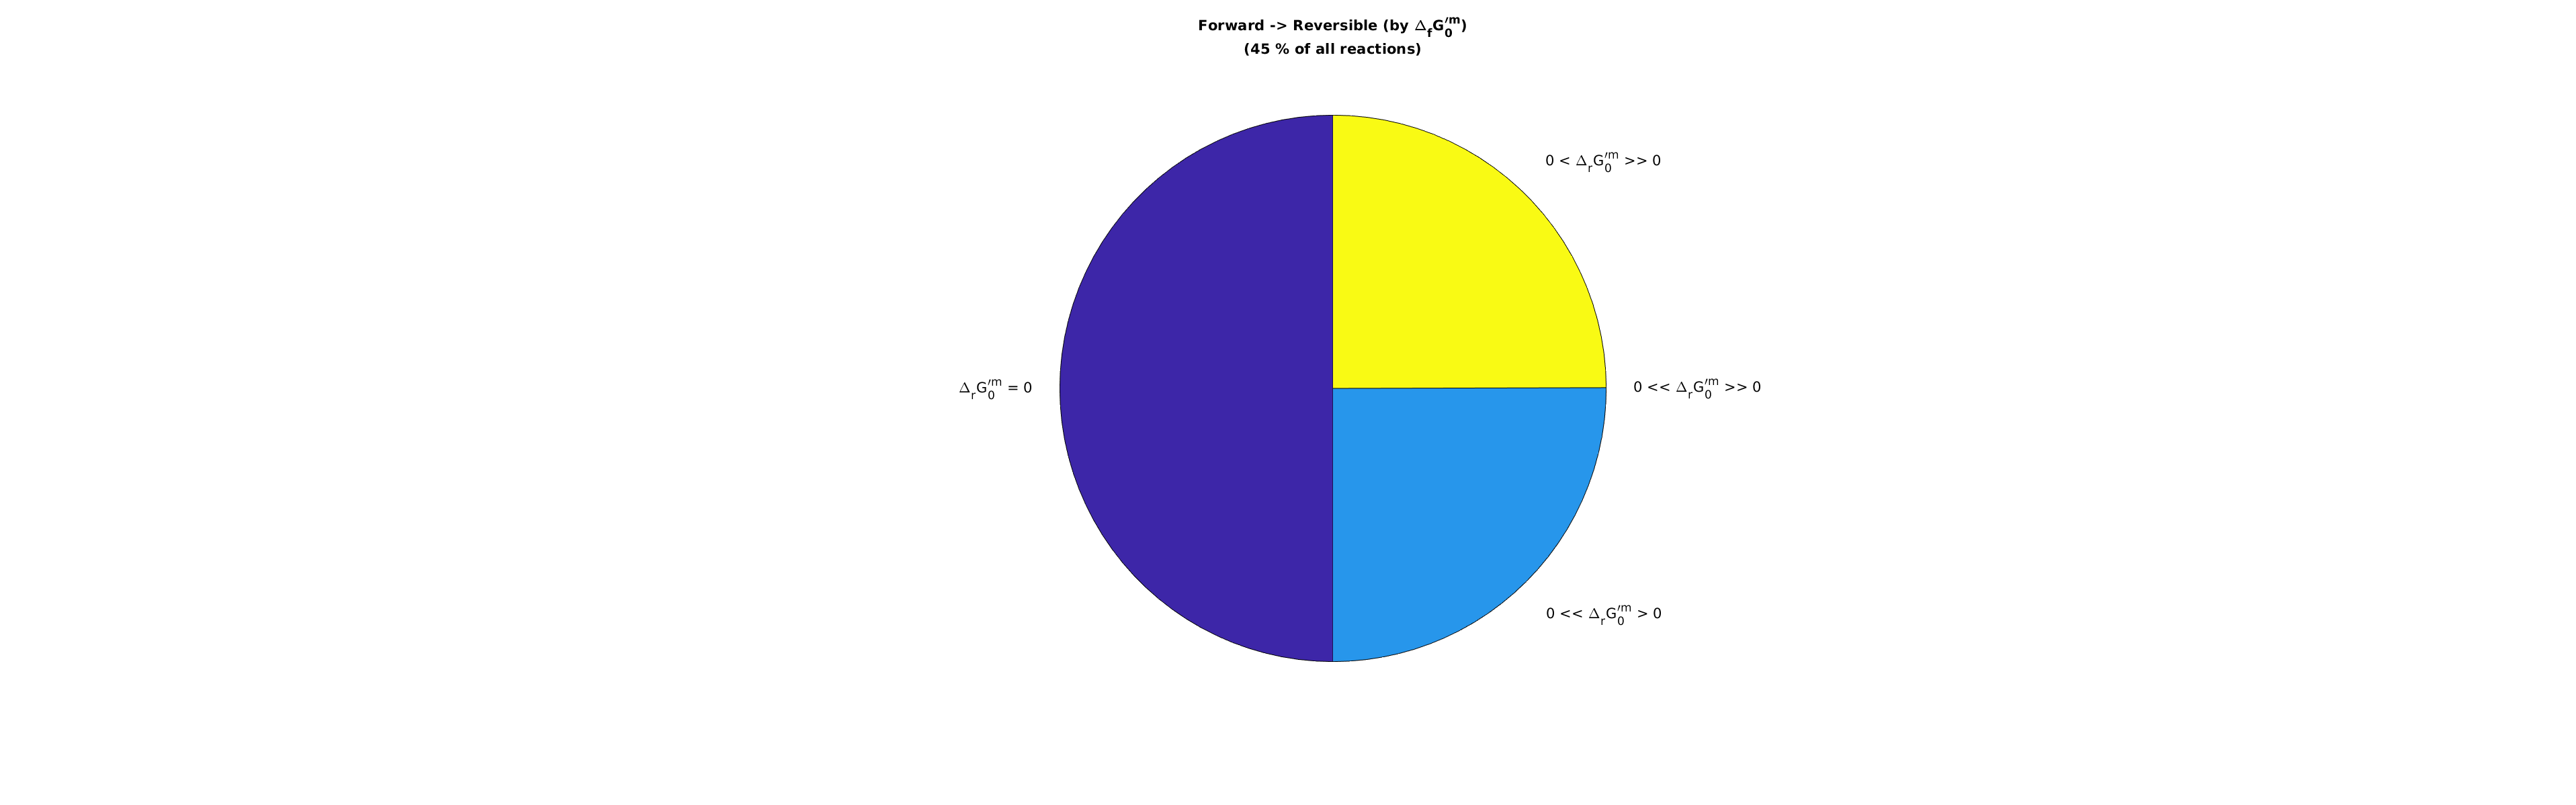

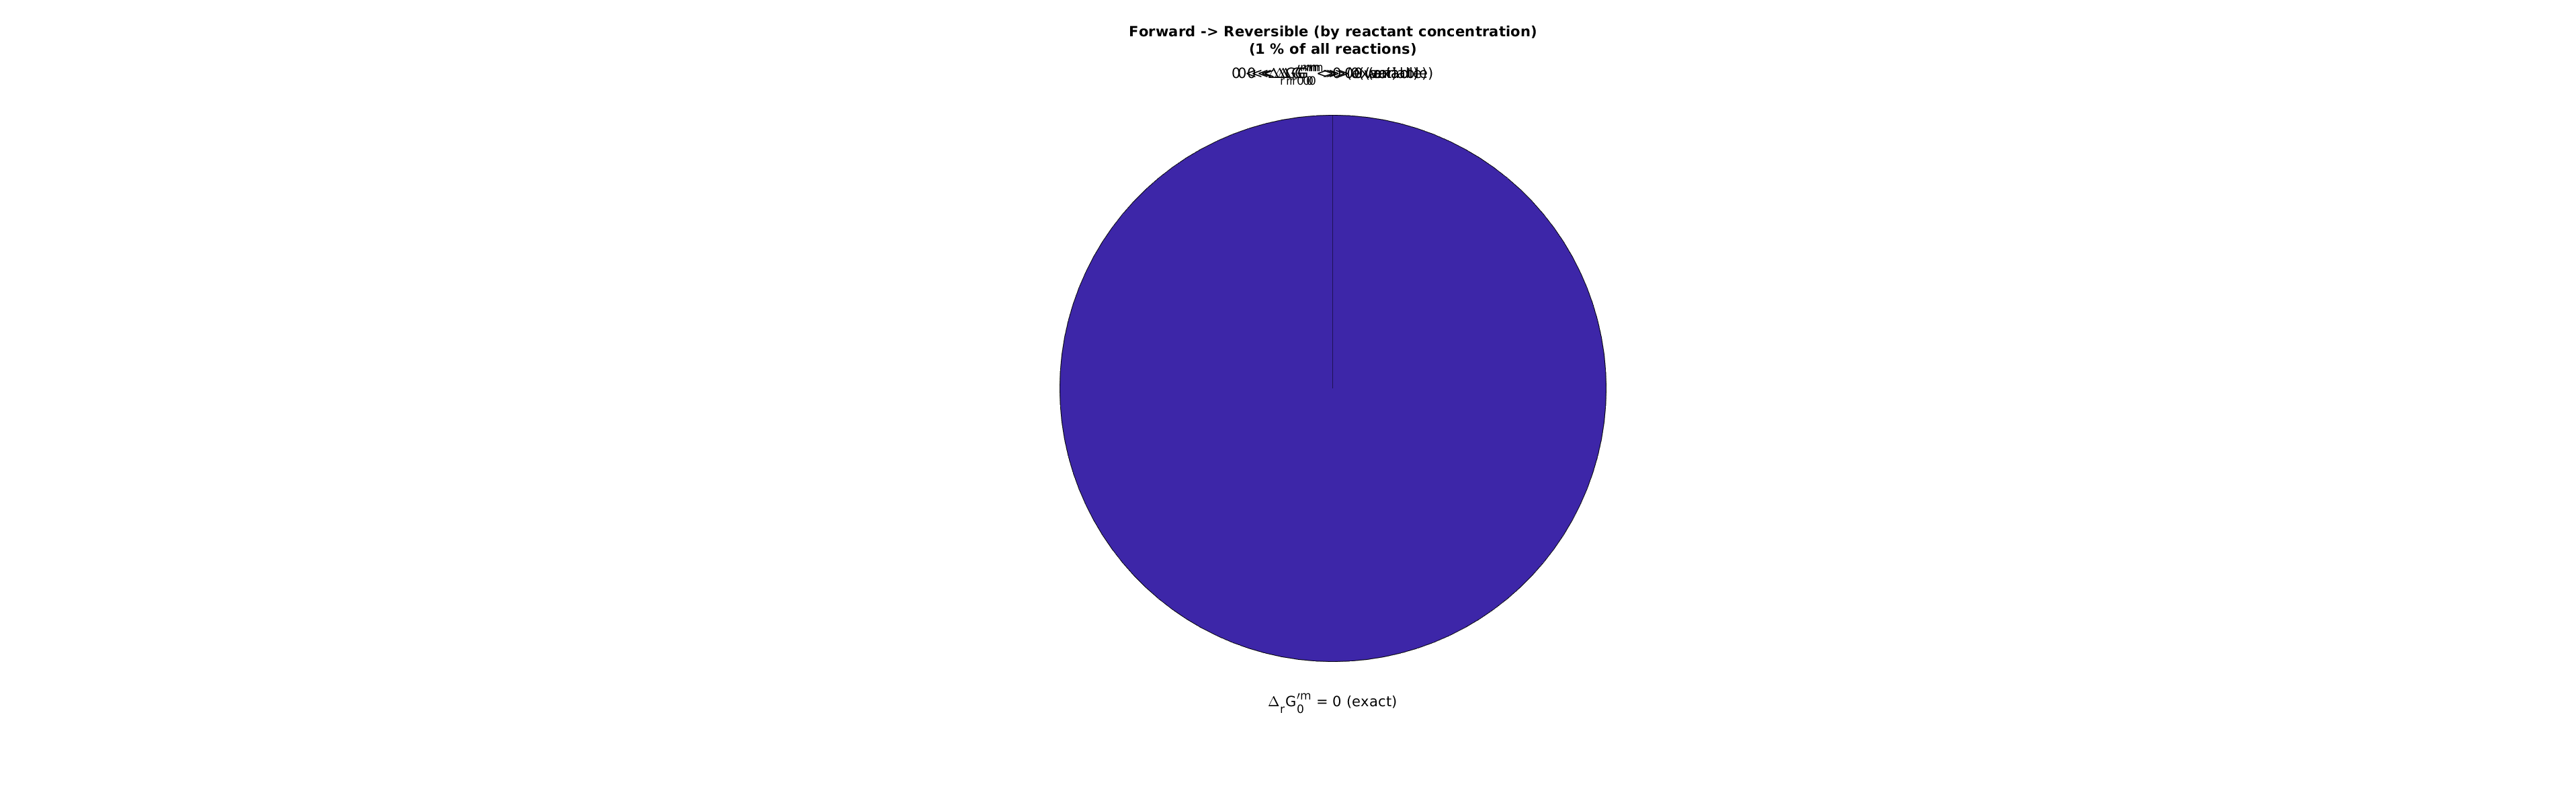

directionalityStatsFigures(directions,resultsBaseFileName)

Generate figures to interpret the overall reasons for reaction directionality changes for the qualitatively forward now quantiatiavely reversible reactions

forwardReversibleFigures...


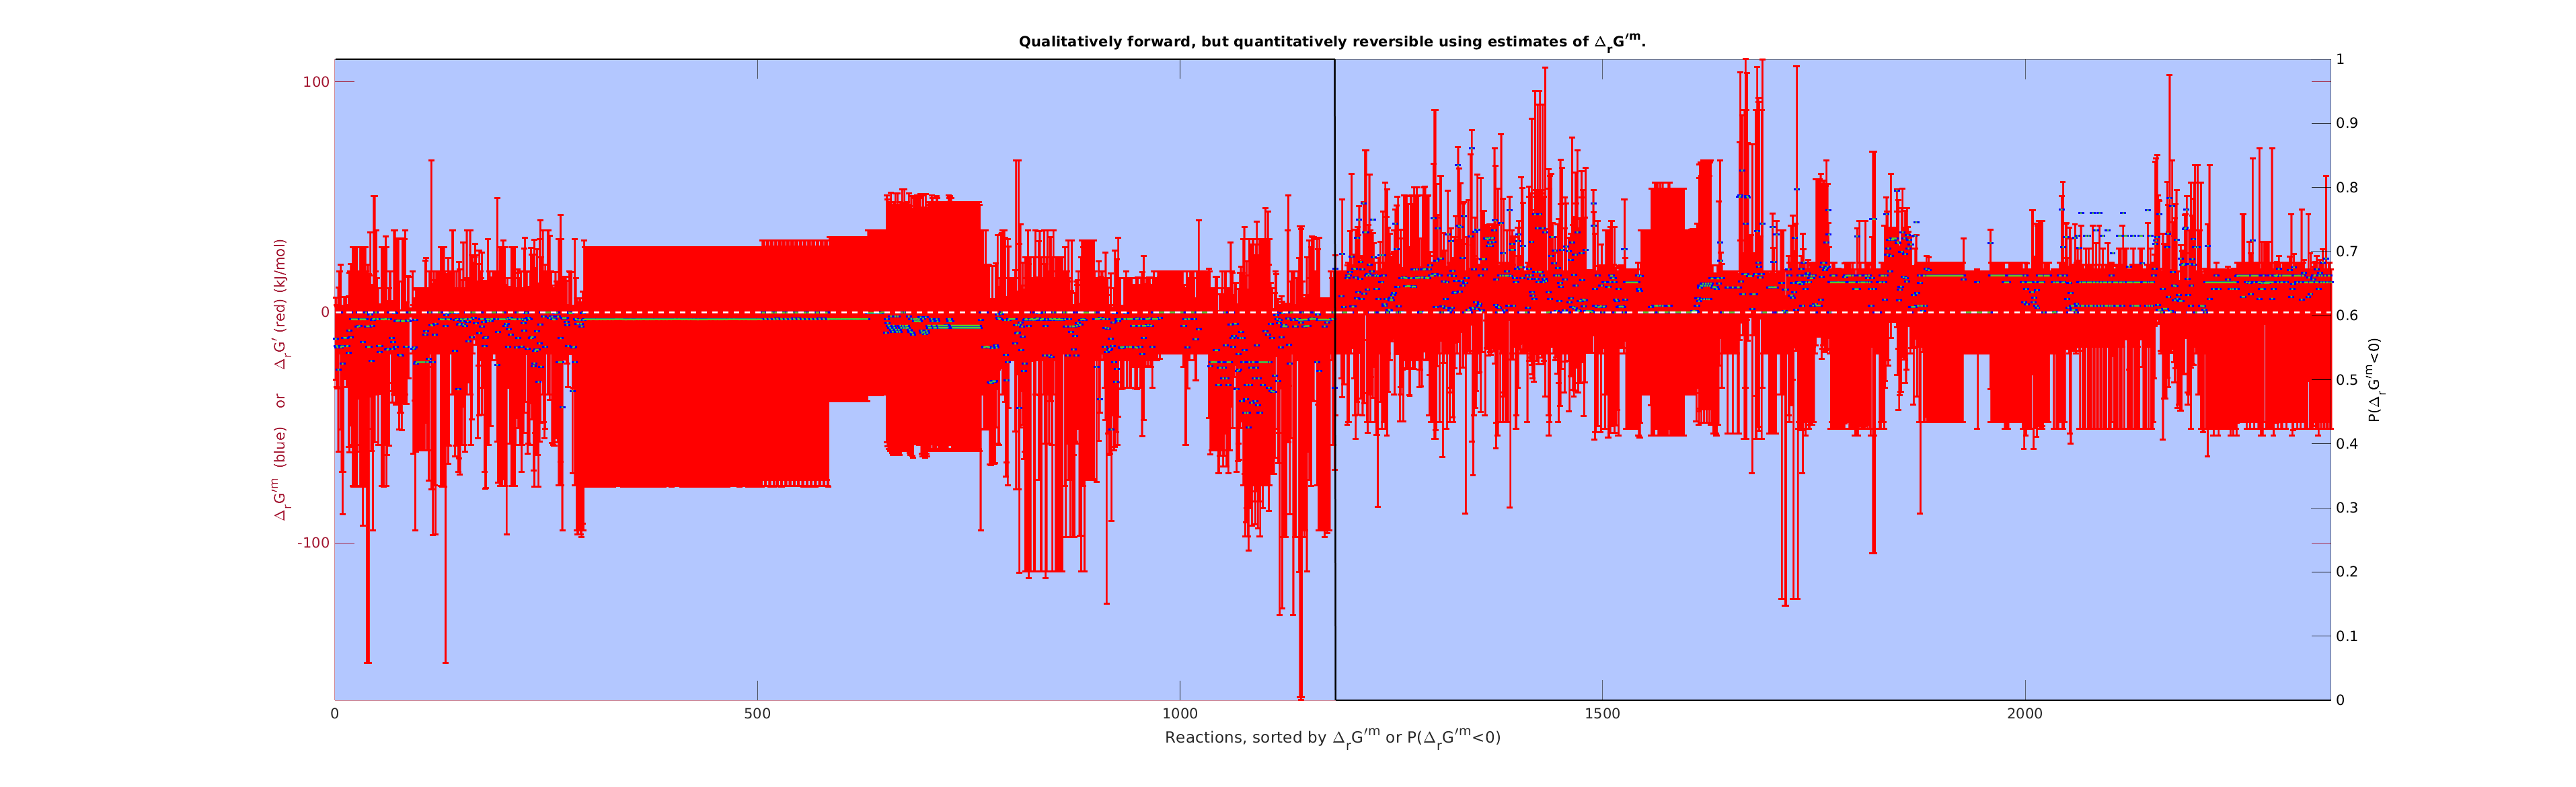

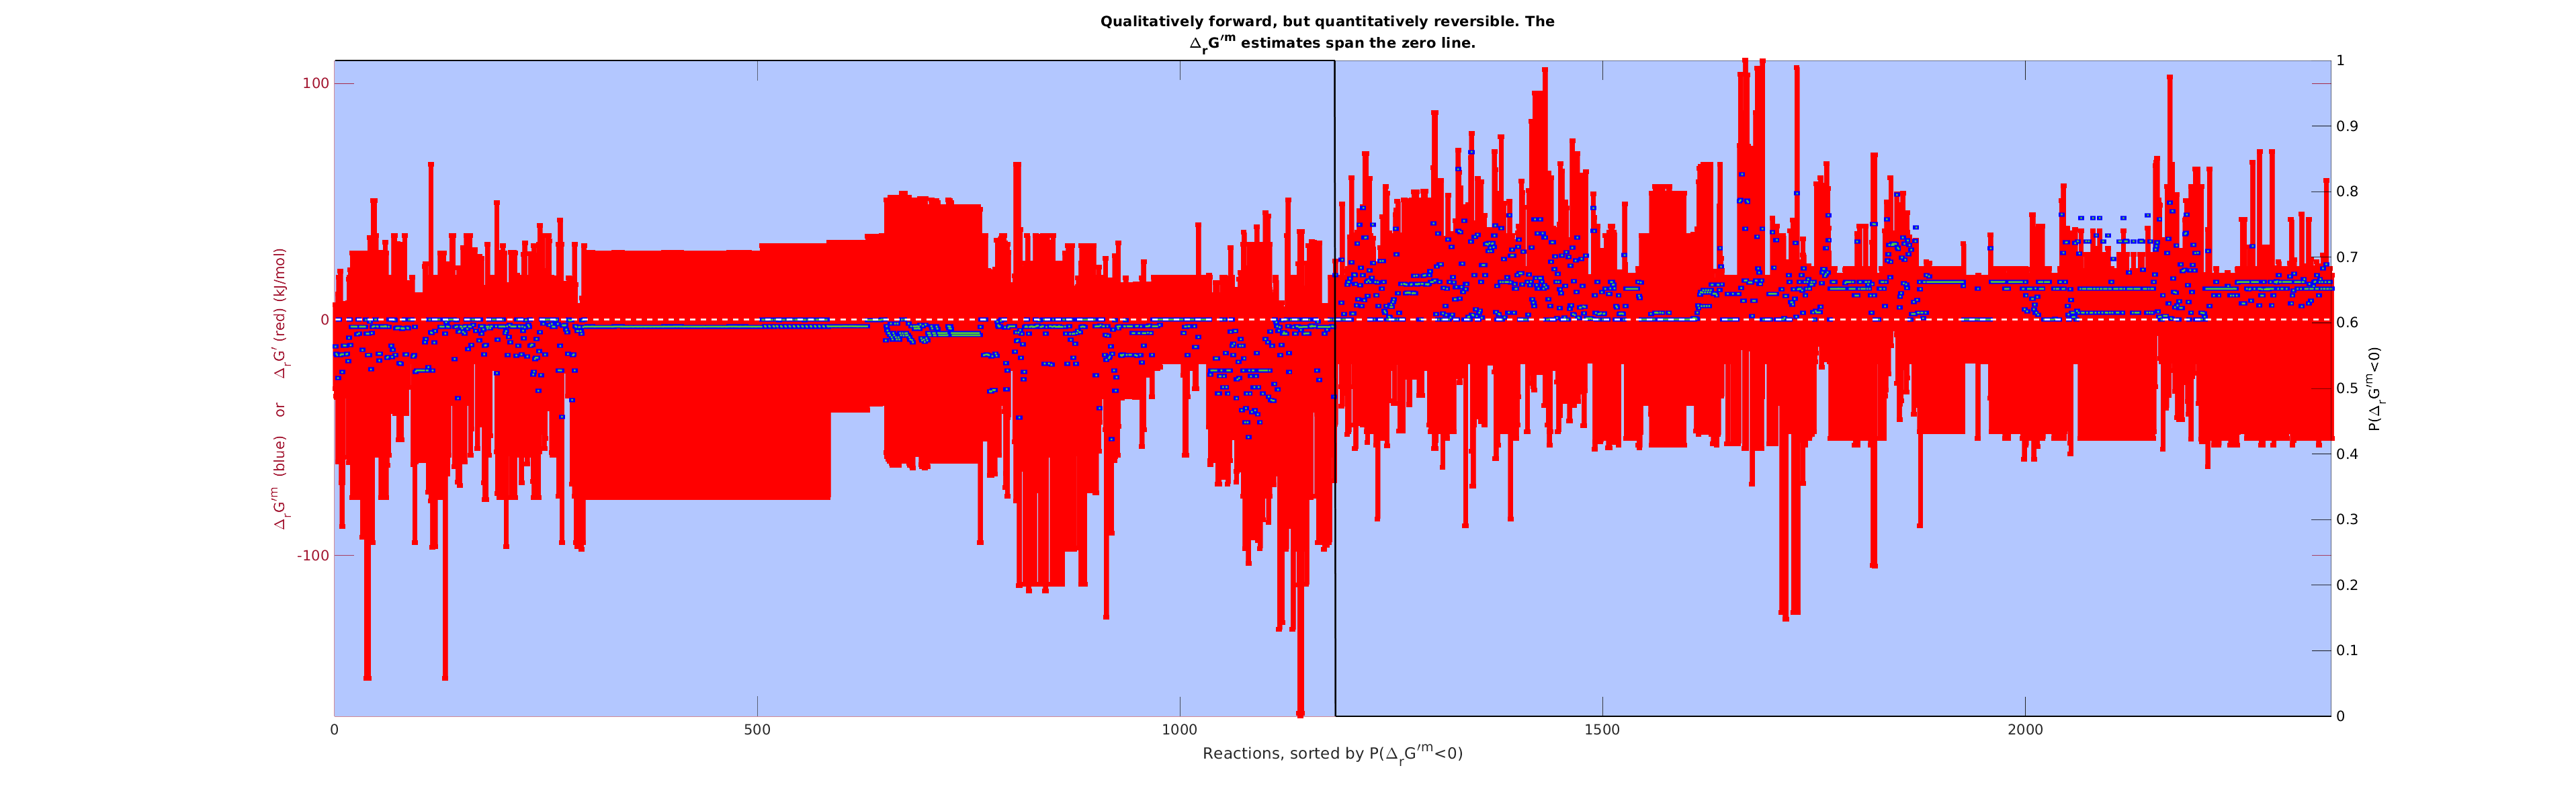

if any(directions.forward2Reversible)
    fprintf('%s\n','forwardReversibleFigures...');
    forwardReversibleFigures(model,directions,confidenceLevel)
end

Write out tables of experimental and estimated thermochemical parameters for the model

generateThermodynamicTables(model,resultsBaseFileName);
save([datestr(now,30) '_' modelName '_thermo'],'model')
save([datestr(now,30) '_vonB_tutorial_complete'])

**REFERENCES**

[1] Fleming, R. M. T. & Thiele, I. von Bertalanffy 1.0: a COBRA toolbox extension to thermodynamically constrain metabolic models. Bioinformatics 27, 142–143 (2011).

[2] Haraldsdóttir, H. S., Thiele, I. & Fleming, R. M. T. Quantitative assignment of reaction directionality in a multicompartmental human metabolic reconstruction. Biophysical Journal 102, 1703–1711 (2012).

[3] Noor, E., Haraldsdóttir, H. S., Milo, R. & Fleming, R. M. T. Consistent Estimation of Gibbs Energy Using Component Contributions. PLoS Comput Biol 9, e1003098 (2013).

[4] Fleming, R. M. T. , Predicat, G.,  Haraldsdóttir, H. S., Thiele, I. von Bertalanffy 2.0 (in preparation).